clear; close all;
[y_wav_01, fs_wav_01]=audioread("D:\matlab\C_01_01(1).wav");
[y_wav_02, fs_wav_02]=audioread("D:\matlab\C_01_02(1).wav");

%Generate long-term spectrum of speech signal
[Pxx, w]=pwelch(repmat(y_wav_01,10,1),[],[],512,fs_wav_01);
%Generate filter coefficients
b=fir2(3000,w/(fs_wav_01 /2),sqrt(Pxx/max(Pxx)));
%generate white noise
N=length(y_wav_01);
noise=1-2*rand(1,N);
%Perform filtering on white noise signal
SNR = -5;
SSN = filter(b,1,noise);
x = y_wav_01';
SSN = SSN * norm(x) / ( 10^(SNR /20) * norm(SSN) );
y = x + SSN;
y = y / norm(y)*norm(x);

% 找带通的区间：把200和7000hz用公式转化到耳蜗的d，把耳蜗的d平均分，然后再用公式转化为f
f_band = [200, 7000];
d_band = log10(f_band ./ 165.4 + 1) / 0.06;

d = linspace(d_band(1), d_band(2), 7);
f = 165.4 .* (10 .^ (0.06 .* d) - 1);

band_fq = [f(1), f(2); f(2), f(3); f(3), f(4); f(4), f(5); f(5), f(6); f(6), f(7)];

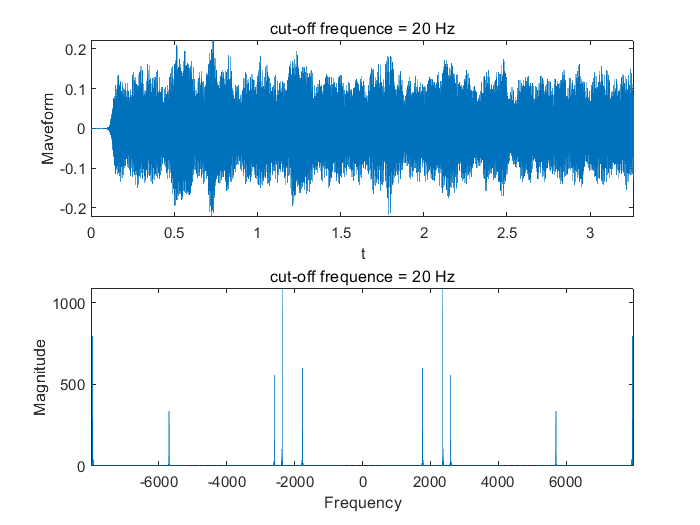

%LPF cut-off frequence = 20 Hz
s_dot_20 = FilterAddNorm(y, band_fq, fs_wav_01, 20, 6);
figure(1);
subplot(2,1,1);plot(linspace(0,N/fs_wav_01,N),s_dot_20);
xlim([0,N/fs_wav_01]);xlabel('t');ylabel('Maveform');title('cut-off frequence = 20 Hz');
subplot(2,1,2);plot(linspace((1-N)/(N/fs_wav_01)/2,(N-1)/(N/fs_wav_01)/2,N),abs(fftshift(fft(s_dot_20))));
xlim([(1-N)/(N/fs_wav_01)/2,(N-1)/(N/fs_wav_01)/2]);xlabel('Frequency');ylabel('Magnitude');title('cut-off frequence = 20 Hz');
audiowrite("D:\matlab\cut_off_frequence_20Hz.wav", s_dot_20, fs_wav_01);
saveas(figure(1),sprintf('1'),'jpg');

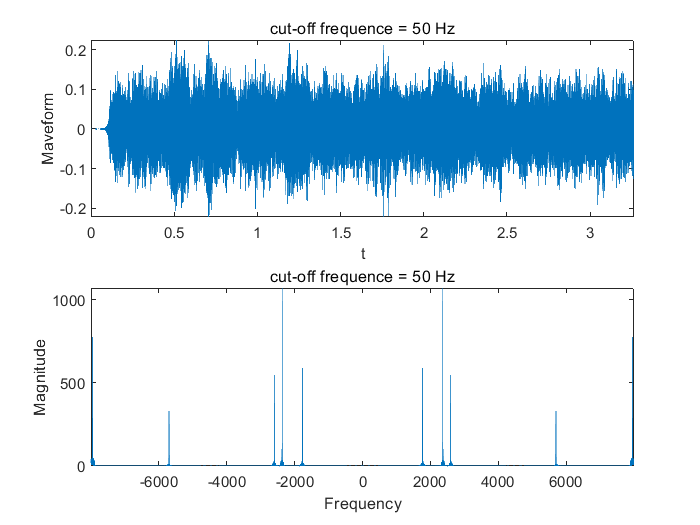

%LPF cut-off frequence = 50 Hz
s_dot_50 = FilterAddNorm(y, band_fq, fs_wav_01, 50, 6);
figure(2);
subplot(2,1,1);plot(linspace(0,N/fs_wav_01,N),s_dot_50);
xlim([0,N/fs_wav_01]);xlabel('t');ylabel('Maveform');title('cut-off frequence = 50 Hz');
subplot(2,1,2);plot(linspace((1-N)/(N/fs_wav_01)/2,(N-1)/(N/fs_wav_01)/2,N),abs(fftshift(fft(s_dot_50))));
xlim([(1-N)/(N/fs_wav_01)/2,(N-1)/(N/fs_wav_01)/2]);xlabel('Frequency');ylabel('Magnitude');title('cut-off frequence = 50 Hz');
audiowrite("D:\matlab\cut_off_frequence_50Hz.wav", s_dot_50, fs_wav_01);
saveas(figure(2),sprintf('2'),'jpg');

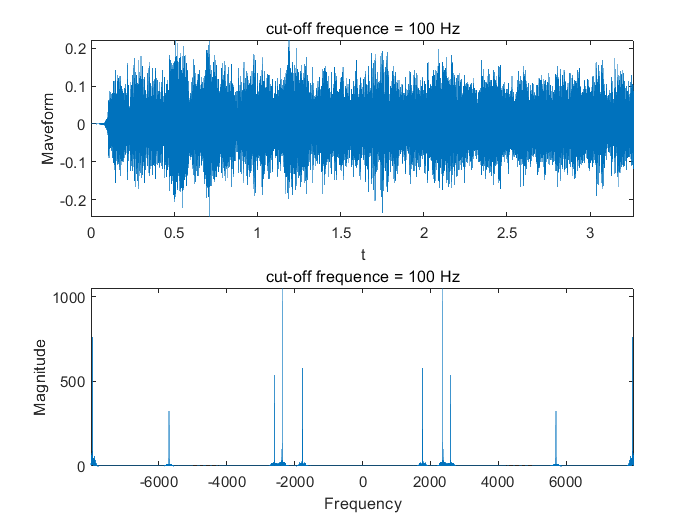

%LPF cut-off frequence = 100 Hz
s_dot_100 = FilterAddNorm(y, band_fq, fs_wav_01, 100, 6);
figure(3);
subplot(2,1,1);plot(linspace(0,N/fs_wav_01,N),s_dot_100);
xlim([0,N/fs_wav_01]);xlabel('t');ylabel('Maveform');title('cut-off frequence = 100 Hz');
subplot(2,1,2);plot(linspace((1-N)/(N/fs_wav_01)/2,(N-1)/(N/fs_wav_01)/2,N),abs(fftshift(fft(s_dot_100))));
xlim([(1-N)/(N/fs_wav_01)/2,(N-1)/(N/fs_wav_01)/2]);xlabel('Frequency');ylabel('Magnitude');title('cut-off frequence = 100 Hz');
audiowrite("D:\matlab\cut_off_frequence_100Hz.wav", s_dot_100, fs_wav_01);
saveas(figure(3),sprintf('3'),'jpg');

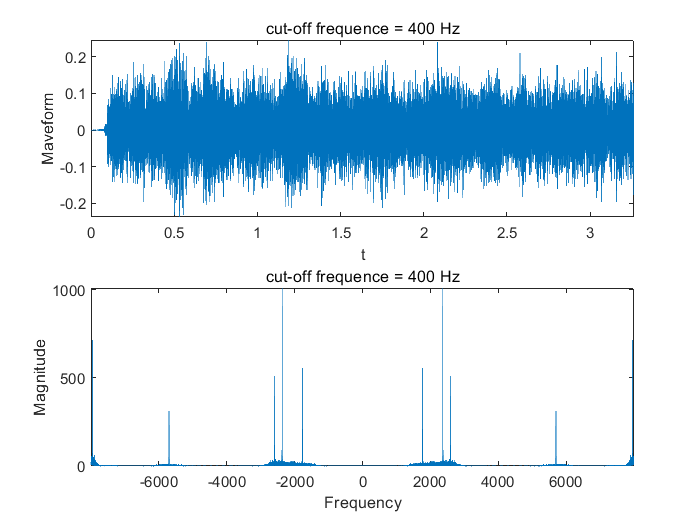

%LPF cut-off frequence = 400 Hz
s_dot_400 = FilterAddNorm(y, band_fq, fs_wav_01, 400, 6);
figure(4);
subplot(2,1,1);plot(linspace(0,N/fs_wav_01,N),s_dot_400);
xlim([0,N/fs_wav_01]);xlabel('t');ylabel('Maveform');title('cut-off frequence = 400 Hz');
subplot(2,1,2);plot(linspace((1-N)/(N/fs_wav_01)/2,(N-1)/(N/fs_wav_01)/2,N),abs(fftshift(fft(s_dot_400))));
xlim([(1-N)/(N/fs_wav_01)/2,(N-1)/(N/fs_wav_01)/2]);xlabel('Frequency');ylabel('Magnitude');title('cut-off frequence = 400 Hz');
audiowrite("D:\matlab\cut_off_frequence_400Hz.wav", s_dot_400, fs_wav_01);
saveas(figure(4),sprintf('4'),'jpg');

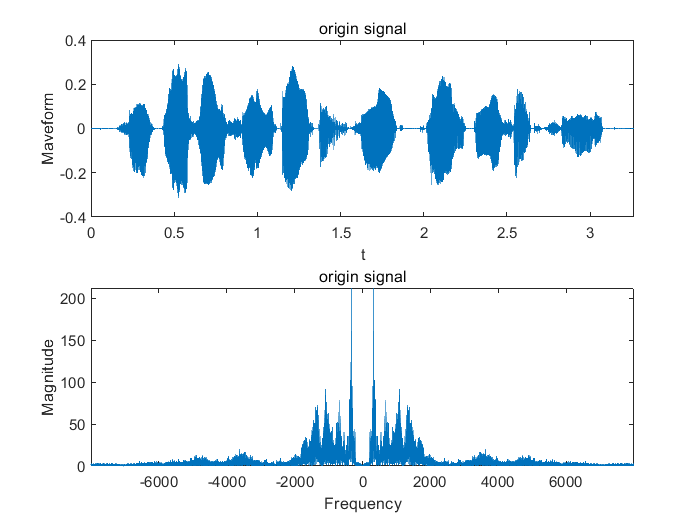

%画原始图像
figure(5);
subplot(2,1,1);plot(linspace(0,N/fs_wav_01,N),y_wav_01);
xlim([0,N/fs_wav_01]);xlabel('t');ylabel('Maveform');title('origin signal');
subplot(2,1,2);plot(linspace((1-N)/(N/fs_wav_01)/2,(N-1)/(N/fs_wav_01)/2,N),abs(fftshift(fft(y_wav_01))));
xlim([(1-N)/(N/fs_wav_01)/2,(N-1)/(N/fs_wav_01)/2]);xlabel('Frequency');ylabel('Magnitude');title('origin signal');
saveas(figure(5),sprintf('5'),'jpg');